# RVC2: Chapter 5

close all
clear all
clc

## 5.1.1.  Braitenberg vehices

Error due to multiple causes.

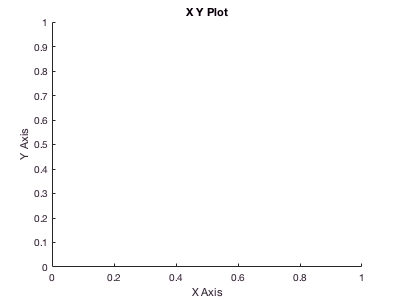

sl_braitenberg
sim('sl_braitenberg');

## 5.1.2  Simple automata

load house
about house

house [double] : 397x596 (1.9 MB)


place

place =      kitchen: [320 190]
      garage: [500 150]
         br1: [50 220]
         br2: [120 50]
         br3: [50 50]
        nook: [320 280]
     mudroom: [320 50]
       patio: [200 350]
       study: [220 50]
      garden: [100 350]
    driveway: [500 350]
      living: [220 200]

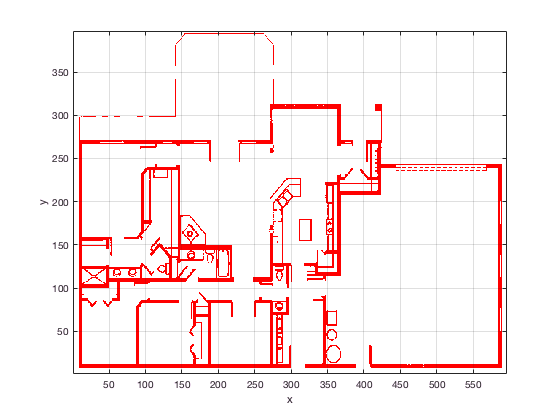


bug = Bug2(house);
bug.plot();

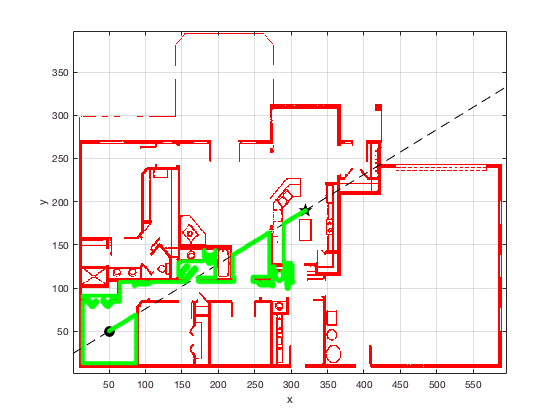

bug.query(place.br3, place.kitchen, 'animate');


p = bug.query(place.br3, place.kitchen)

p =     51    51
    52    51
    53    52
    54    52
    55    53
    56    53
    57    54
    58    54
    59    55
    60    55

about(p)

p [double] : 1299x2 (20.8 kB)


%p = bug.query([], place.kitchen);  % this requires the user to prompt for a start location


## Sidebar: Making a map (page 131)

map = zeros(100, 100);
map(40:50,20:80) = 1;
%map = makemap(100)  % this requires user input

## 5.2.1  Distance transform

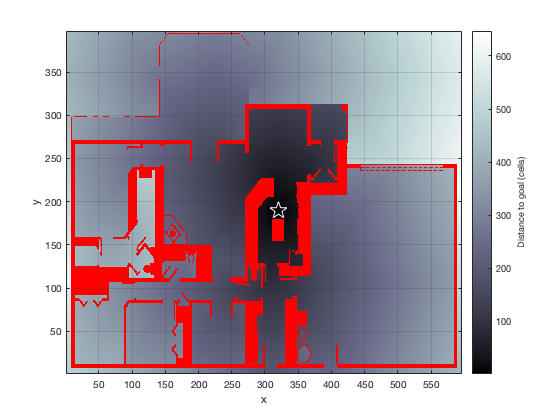

dx = DXform(house);
dx.plan(place.kitchen)

dx.plot()

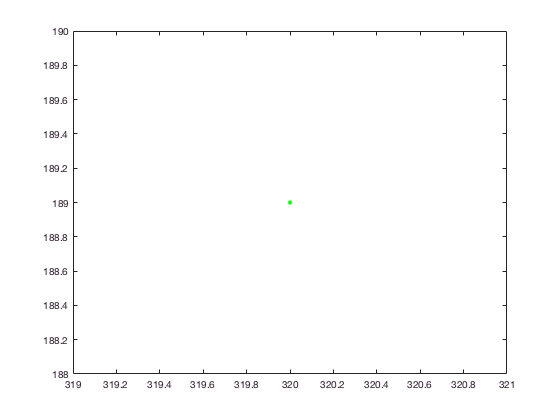


dx.query(place.br3, 'animate');

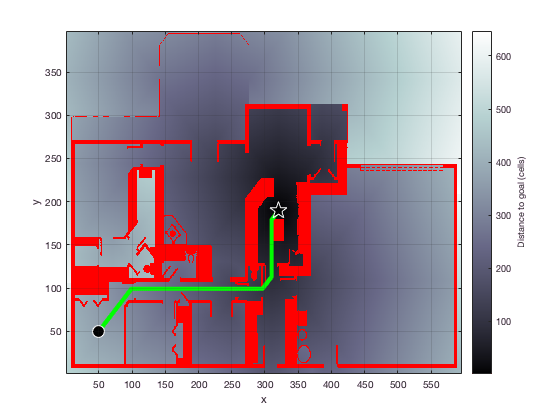


p = dx.query(place.br3);

dx.plot(p)


numrows(p)

ans = 336

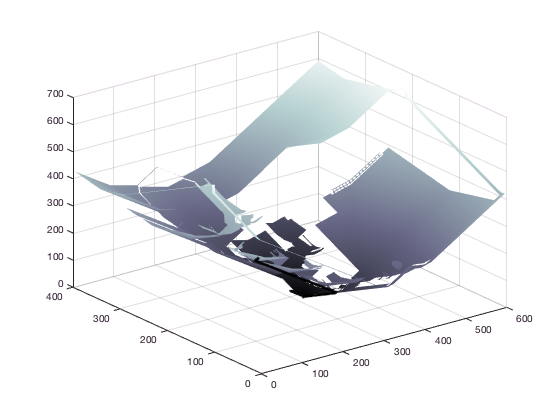


dx.plan(place.kitchen, 'animate');

dx.plot3d(p)

and now we inflate the obstacles

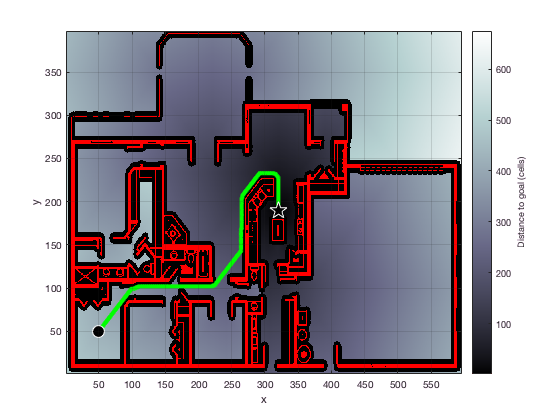

dx = DXform(house, 'inflate', 5);
dx.plan(place.kitchen)
p = dx.query(place.br3);
dx.plot(p)

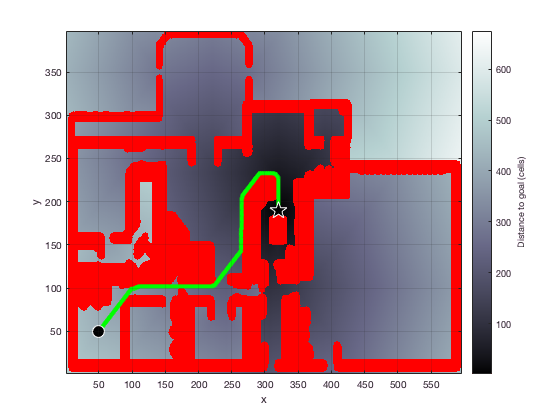


dx.plot(p, 'inflated')

## Sidebar: Navigation class (page 132)

This code is by way of example and won't actually run.  You'd need to define world, start, goal and use a concrete subclass of Navigation instead of MyNavClass (eg. DXform or PRM)

% nav = MyNavClass(world)
% nav.plan()
% nav.plan(goal)
% 
% p = nav.query(start, goal)
% p = nav.query(start)
% nav.plot()
% nav.plot(p)

## 5.2.2  D*

ds = Dstar(house);
c = ds.costmap();
ds.plan(place.kitchen);
ds.niter

ans = 245184

ds.query(place.br3);

ds.modify_cost( [300,325; 115,125], 5 );

ds.plan();
ds.niter
ds.query(place.br3);

## 5.2.3  Introduction to roadmap methods

free = 1 - house;
free(1,:) = 0; free(100,:) = 0;
free(:,1) = 0; free(:,100) = 0;
skeleton = ithin(free);

## 5.2.4 PRM

prm = PRM(house)

prm = 
PRM navigation class:    
  occupancy grid: 397x596
  graph size:            
  dist thresh:           
  2 dimensions           
  0 vertices             
  0 edges                
  0 components           


randinit
prm.plan('npoints', 150)
prm

prm = 
PRM navigation class:    
  occupancy grid: 397x596
  graph size: 150        
  dist thresh: 178.8     
  2 dimensions           
  150 vertices           
  1223 edges             
  14 components          


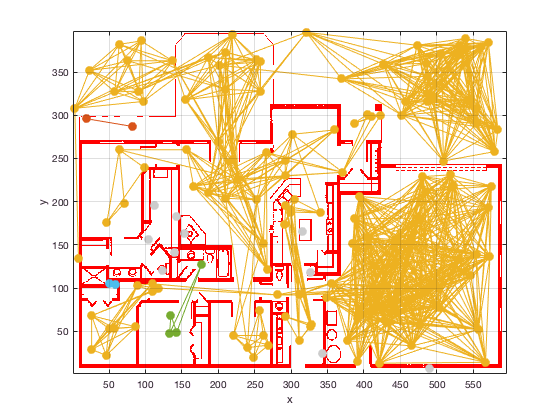

prm.plot()


p = prm.query(place.br3, place.kitchen);
about p

p [double] : 9x2 (144 bytes)


## Sidebar: Voronoi tessellation (page 137)

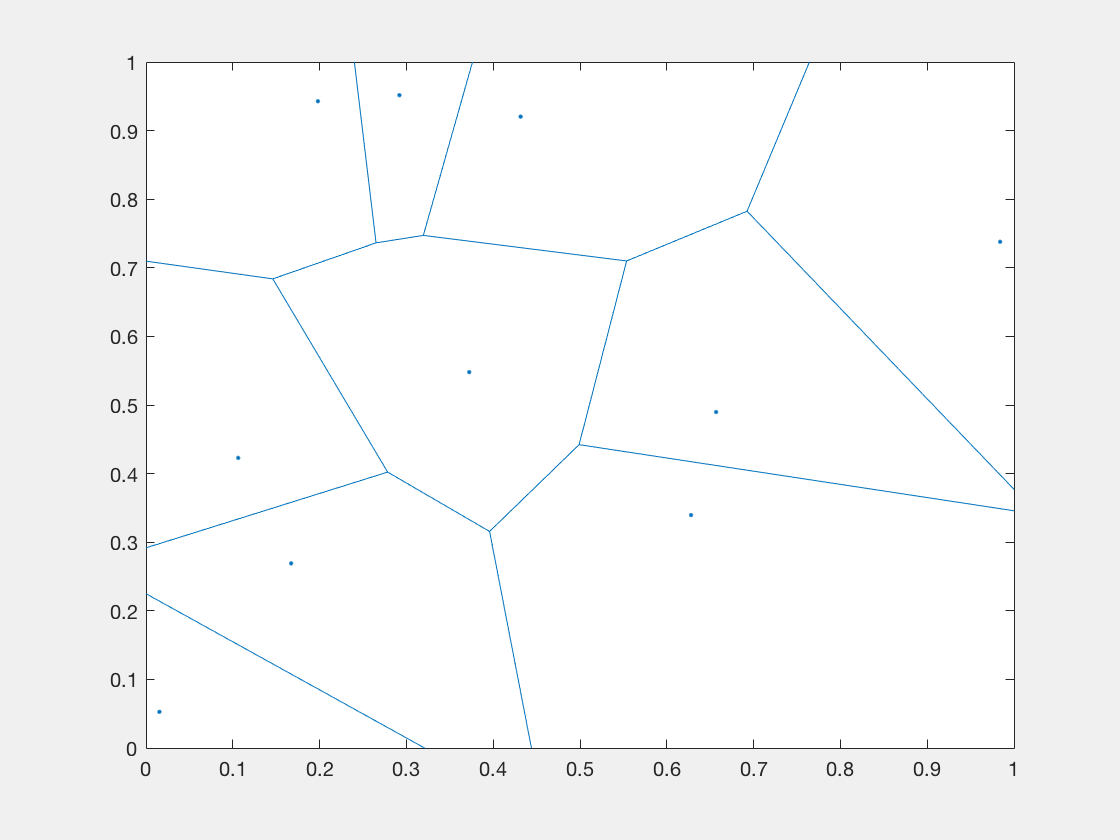

sites = rand(10, 2);
voronoi(sites(:,1), sites(:,2))

## Sidebar: random numbers (page 139)

rand

ans = 0.4177

rand

ans = 0.9831

rand

ans = 0.3015

randinit
rand

ans = 0.8147

rand

ans = 0.9058

## 5.2.4 Lattice planner

lp = Lattice();
lp.plan('iterations', 2)

13 nodes created


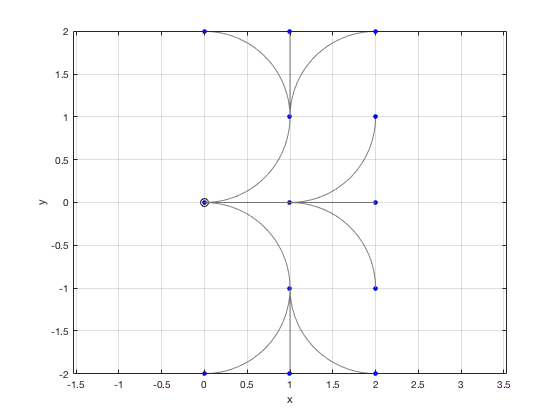

lp.plot()


lp.plan('iterations', 8)

780 nodes created


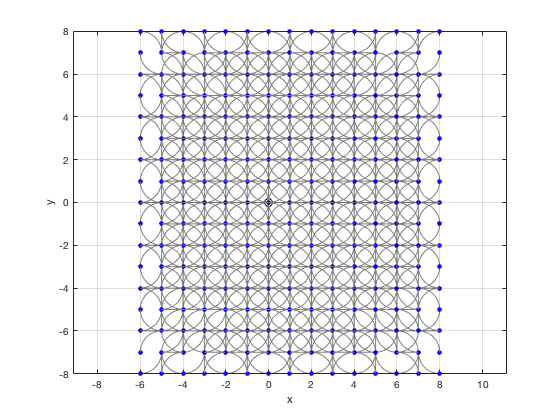

lp.plot()


lp.query( [1 2 pi/2], [2 -2 0] );

A* path cost 6


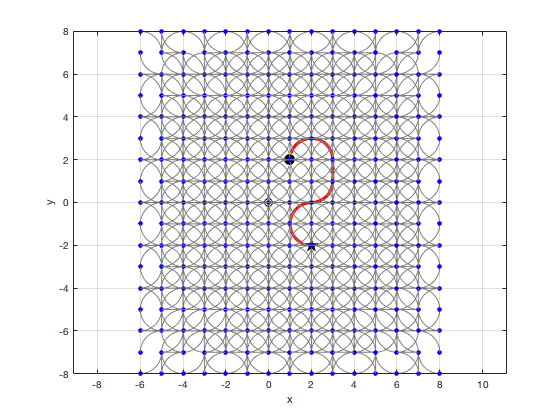


lp.plot()


p = lp.query( [1 2 pi/2], [2 -2 0] )

A* path cost 6


p =     1.0000    2.0000    1.5708
    2.0000    3.0000         0
    3.0000    2.0000   -1.5708
    3.0000    1.0000   -1.5708
    2.0000    0.0000   -3.1416
    1.0000   -1.0000   -1.5708
    2.0000   -2.0000         0

about p

p [double] : 7x3 (168 bytes)



lp.plan('cost', [1 10 10])

780 nodes created


lp.query( [1 2 pi/2], [2 -2 0] );

A* path cost 35


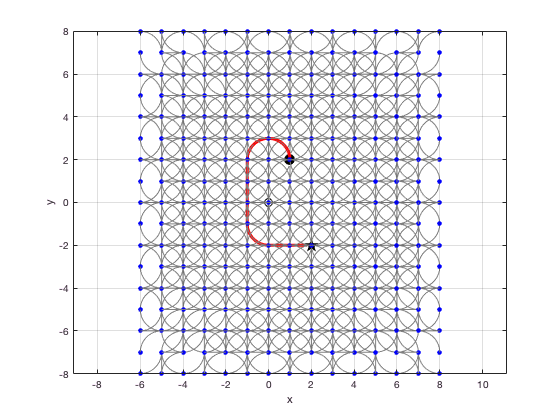

lp.plot()


load road
lp = Lattice(road, 'grid', 5, 'root', [50 50 0])

lp = 
Lattice navigation class:
  occupancy grid: 80x100 
  grid spacing: 5        
  costs [1,1,1]          
  iterations Inf         
 Graph:                  
  3 dimensions           
  0 vertices             
  0 edges                
  0 components           


lp.plan();

718 nodes created


lp.query([30 45 0], [50 20 0])

A* path cost 5


## 5.2.5 Rapidly exploring random trees (RRT)

car = Bicycle('steermax', 0.5);
rrt = RRT(car, 'npoints', 1000)

rrt = 
RRT navigation class:                                   
  occupancy grid: 0x0                                   
  region: X -5.000000 : 5.000000; Y -5.000000 : 5.000000
  sim time: 0.500000                                    
  speed: 1.000000                                       
 Graph:                                                 
  3 dimensions                                          
  0 vertices                                            
  0 edges                                               
  0 components                                          
Bicycle object                                          
  L=1                                                   
  Superclass: Vehicle                                   
    max speed=1, max steer input=0.5, dT=0.1, nhist=0   
    configuration: x=0, y=0, theta=0                    


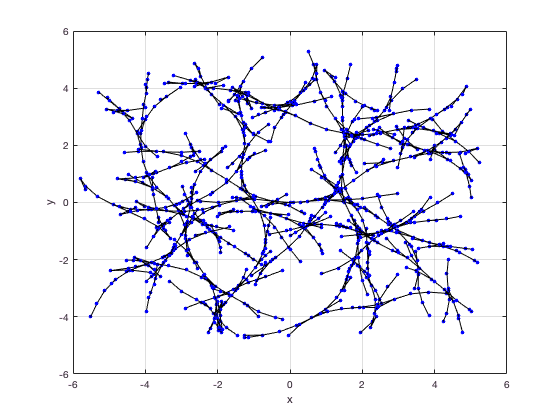


rrt.plan();
rrt.plot();


rrt = RRT(car, road, 'npoints', 1000, 'root', [50 22 0],'simtime', 4)

rrt = 
RRT navigation class:                                    
  occupancy grid: 80x100                                 
  region: X 1.000000 : 100.000000; Y 1.000000 : 80.000000
  sim time: 4.000000                                     
  speed: 1.000000                                        
 Graph:                                                  
  3 dimensions                                           
  0 vertices                                             
  0 edges                                                
  0 components                                           
Bicycle object                                           
  L=1                                                    
  Superclass: Vehicle                                    
    max speed=1, max steer input=0.5, dT=0.1, nhist=5    
    configuration: x=3.48359, y=1.83414, theta=-0.796894 


rrt.plan();

p = rrt.query([40 45 0], [50 22 0]);

Index exceeds matrix dimensions.
Error in PGraph/distance_metric (line 1316)
                        d(3,:) = angdiff(x1(3), x2(3,:));
Error in PGraph/distance (line 546)
            d = g.distance_metric( g.vertexlist(:,v1), g.vertexlist(:,v2));
Error in PGraph/Astar (line 1225


about p

rrt.plot(p)

plot_vehicle(p, 'box', 'size', [20 30], 'fill', 'r', 'alpha', 0.1)


bdclose('all')